# External ANC vs Internal ANC Analysis Code

Calculates the average difference between the External ANC (ExA) and Internal ANC (InA). Data from Arm 1 is used for width and density.  

### Cassady S. Olson 

Load data and set color parameters

clear 

% Load in data
% Add data folder to path
addpath("data\")
% arm 1 data
load("Arm1_Measurement.mat")

%cross sectional area data
load("xSectArea.mat");



% figure color parameters
blue = [0,0,255/255]; 
blue2 = [0, 150/255, 255/255];
orange = [255/255,165/255,0];
orange2 = [204/255, 85/255, 0/255];

% Proximal - distal tag
posID = [1,2,3];
% Number of points along proximal - distal axis
numPos = 3;
ExIn = 2;
posLabel = {'Proximal', 'Intermediate', 'Distal'};

## ExA vs InA Segment Width 

Calculate the average and SEM of the segments subdivided by those on the ExA vs InA.

% arm 1 segments
segWidth = Measurement.segWidth; 

avgWidthTotal = [];
semWidthTotal = []; 
widthEx = [];
widthIn = [];
for n = 1:numPos
    for m = 1:ExIn
        both = find(segWidth(:, 5) == m & segWidth(:, 2) == n);
        if m == 2
            widthEx = [widthEx, segWidth(both, 1)];
        elseif m == 1 
            widthIn = [widthIn, segWidth(both, 1)];
        end 
        avgWidthTotal(n, m) = mean(segWidth(both, 1));
        semWidthTotal(n, m) = std(segWidth(both, 1))./sqrt(length(segWidth(both,1)));
    end
end

Run stats to compute significance down the proximal-distal axis and between ExA and InA

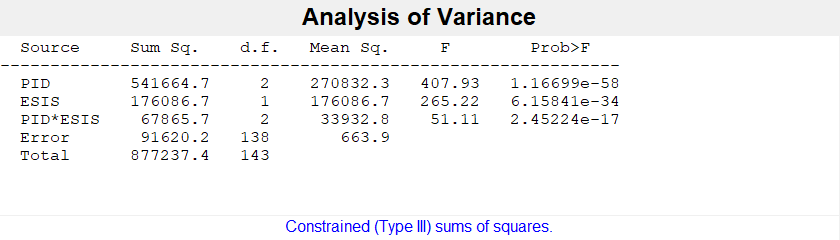

[p1, table1, stats1] = anovan(segWidth(:,1), {segWidth(:,2), segWidth(:,5)},'model', 'interaction','varnames', {'PID', 'ESIS'});

Run post hoc

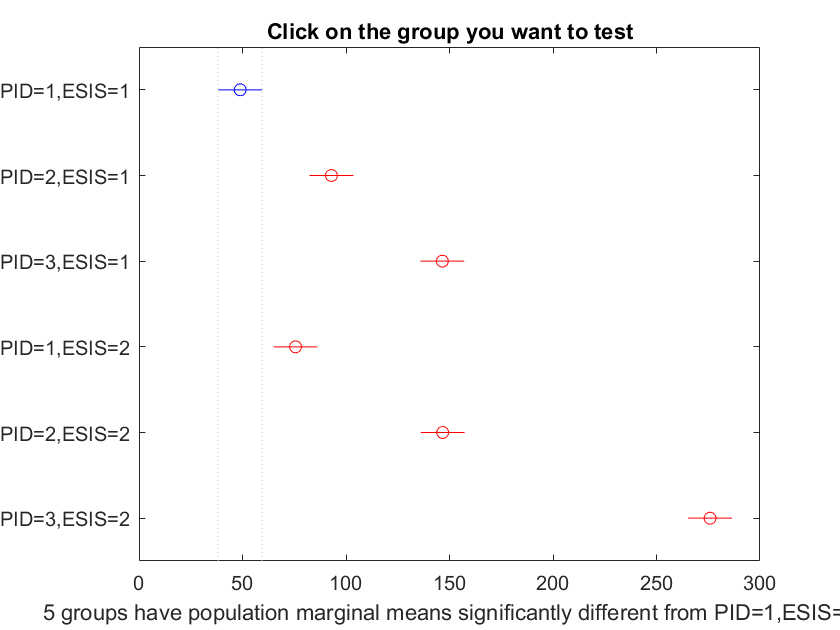

[c1, ~, h1] = multcompare(stats1, "Dimension",[1,2]);

Generate plot with significance stars 

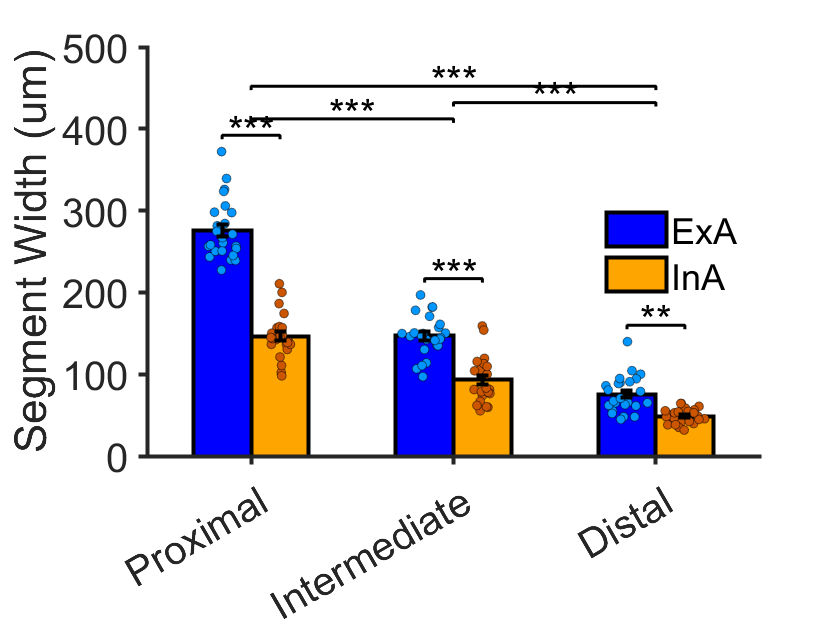

clear z

% Plot with stars
figure, 
b = bar(flip(flip(avgWidthTotal,2)), 'LineWidth', 2, 'BarWidth',1);
hold on 

[ngroups,nbars] = size(avgWidthTotal);

% Get the x coordinate of the bars
for i = 1:nbars
    z(i,:) = b(i).XEndPoints;
end
z = z';

% add swarmchart
numCon = size(reshape(widthIn, 1, []),2)/size(z,1);
makeAxis1 = repmat(z(:,2),[1, numCon]);
xValues1 = reshape(makeAxis1.',1,[]);
makeAxis3 = repmat(z(:,1),[1, numCon]);
xValues3 = reshape(makeAxis3.',1,[]);

swarmchart(xValues1', flip(reshape(widthIn, 1, [])), 20,orange2,'Filled','MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5,'XJitter', 'density', 'XJitterWidth',0.25);
swarmchart(xValues3', flip(reshape(widthEx, 1, [])), 20,blue2,'Filled','MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5,'XJitter', 'density', 'XJitterWidth',0.25);

% add errorbar
er = errorbar(z,flip(flip(avgWidthTotal,2)), flip(flip(semWidthTotal,2)), 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 2);   

% Use sigstar to add stars
% select significance values for relavent groups 
comp = [5, 6; 4, 5; 4, 6; 3, 6; 2, 5; 1, 4];
for get = 1:length(comp)
    indx = find(comp(get, 1) == c1(:, 1) & comp(get, 2) == c1(:,2));
    pVal(get) = c1(indx, end); 
end

% array of comparision groups 
groups = {[1,2], [2,3], [1, 3], z(1,:), z(2, :), z(3, :)}; 

% add stars
a = sigstar(groups, pVal);
set(a(:,2),'FontSize',20)


% Set plot parameters 
b(1,1).FaceColor = blue;
b(1, 2).FaceColor = orange;

legend('ExA', 'InA', 'Location', 'east', 'TextColor', 'k')
legend('boxoff')
xticklabels((posLabel))
ylabel('Segment Width (um)')
axis normal
ax = gca; 
ax.FontSize = 20;
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 2;
xticks([1,2,3])
ylim([0,500])

%yticks([0:500])

## External ANC vs Internal ANC Cell density 

Calculate the average and SEM of the cell density from segments subdivided by ExA and InA. 

% arm 1 desnity 
density = Measurement.density;

avgDens = [];
semDens = [];
densEx = [];
densIn = [];

for n = 1:numPos
    for m = 1:ExIn
        both = find(density(:, 4) == n & density(:, 7) == m);
         if m == 2
            densEx = [densEx, density(both, 3)];
        elseif m == 1 
            densIn = [densIn, density(both, 3)];
        end 
        avgDens(n, m) = mean(density(both, 3));
        semDens(n, m) = std(density(both, 3))./sqrt(length(density(both,3)));
    end
end


Run stats to compute significance down the proximal-distal axis and between ExA and InA

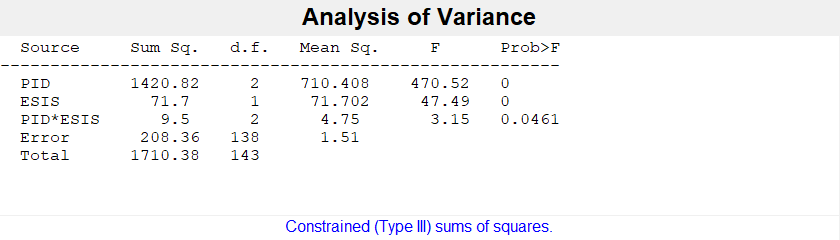

[p2, table2, stats2] = anovan(density(:,3), {density(:,4), density(:,7)}, 'model', 'interaction', 'varnames', {'PID', 'ESIS'});

Run post hoc

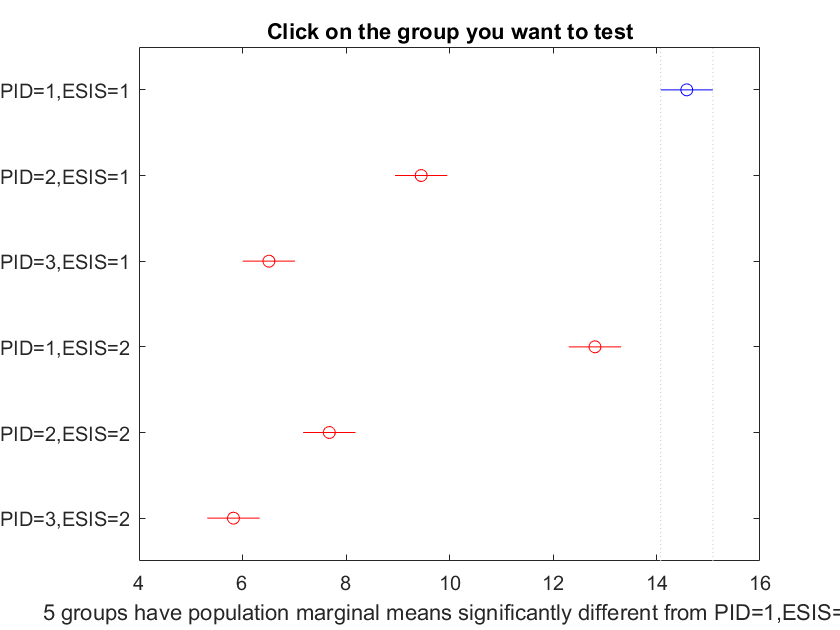

c2 = multcompare(stats2, "Dimension",[1,2]);

Generate plot with significance stars

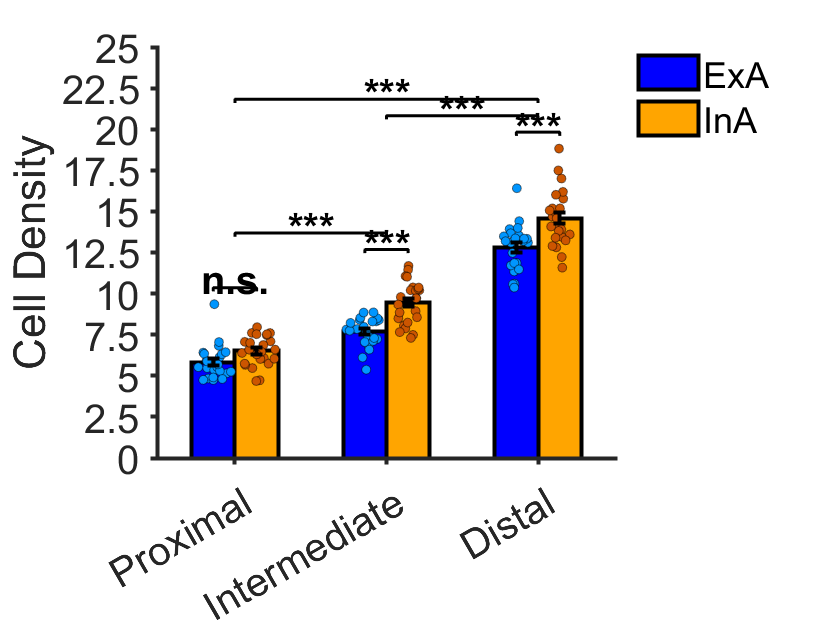

clear w 

% Plot with stars
figure,
b = bar(flip(flip(avgDens,2)), 'LineWidth', 2, 'BarWidth',1);
hold on 
[ngroups,nbars] = size(avgDens);
% Get the x coordinate of the bars
w = nan(nbars, ngroups);
for i = 1:nbars
    w(i,:) = b(i).XEndPoints;
end
w = w'; 

% add swarmchart
numCon = size(reshape(densIn, 1, []),2)/size(w,1);
makeAxis1 = repmat(w(:,2),[1, numCon]);
xValues1 = reshape(makeAxis1.',1,[]);
makeAxis3 = repmat(w(:,1),[1, numCon]);
xValues3 = reshape(makeAxis3.',1,[]);

swarmchart(xValues1', flip(reshape(densIn, 1, [])), 20,orange2,'Filled','MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5,'XJitter', 'density', 'XJitterWidth',0.25);
swarmchart(xValues3', flip(reshape(densEx, 1, [])), 20,blue2,'Filled','MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5,'XJitter', 'density', 'XJitterWidth',0.25);

% add errorbar 
er = errorbar(w,flip(flip(avgDens,2)), flip(flip(semDens,2)), 'LineStyle','none', 'Color', 'k', 'LineWidth', 2);  

% Use sigstar to add stars
% select significance values for relavent groups 
for get = 1:length(comp)
    indx = find(comp(get, 1) == c2(:, 1) & comp(get, 2) == c2(:,2));
    pVal1(get) = c2(indx, end); 
end
% array of comparision groups 
groups = {[1,2], [2,3], [1, 3], w(1,:), w(2, :), w(3, :)}; 
% Add stars
a1 = sigstar(groups, pVal1);
set(a1(:,2),'FontSize',20, 'FontWeight', 'bold')
set(a1, 'Color', 'k')

% Set plot parameters 
b(1, 1).FaceColor = blue;
b(1, 2).FaceColor = orange;
legend('ExA', 'InA', 'Location','northeastoutside','TextColor', 'k')
legend('boxoff')
xticklabels((posLabel))
ylabel('Cell Density')
ylim([0,25])
yticks(0:2.5:25)
axis normal
ax = gca; 
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 2;
xticks([1,2,3])
ax.FontSize = 20;

## External ANC vs Internal ANC Cross Sectional Area

Calculate the cross sectional area for segments from the external and internal ANC. Measurements from a horizontally sectioned ANC stained with acetylated alpha tubulin. 

% Calculate cross sectional area
widthX = xSectArea.width;
height = xSectArea.height;
area = widthX(:,1).*height(:, 1);


Find average cross sectional area by ANC level and internal vs external

levels = [1, 2, 3, 4];
inOut = [1,2]; 
numLevels = 4;

splitArea = zeros(4, 2);
splitSEM = zeros(4, 2);

for here = 1:numLevels
    thisLevel = levels(here); 
    levelIDX = widthX(:,2) == thisLevel; 
    theseTags = widthX(levelIDX, 4);
    thisArea = area(levelIDX, 1)./1000;
    [splitArea(here, :), splitSEM(here, :)] = GroupAvgSem(thisArea, theseTags, inOut);
end

splitArea = flip(splitArea,2);
splitSEM = flip(splitSEM, 2);

Generate plot

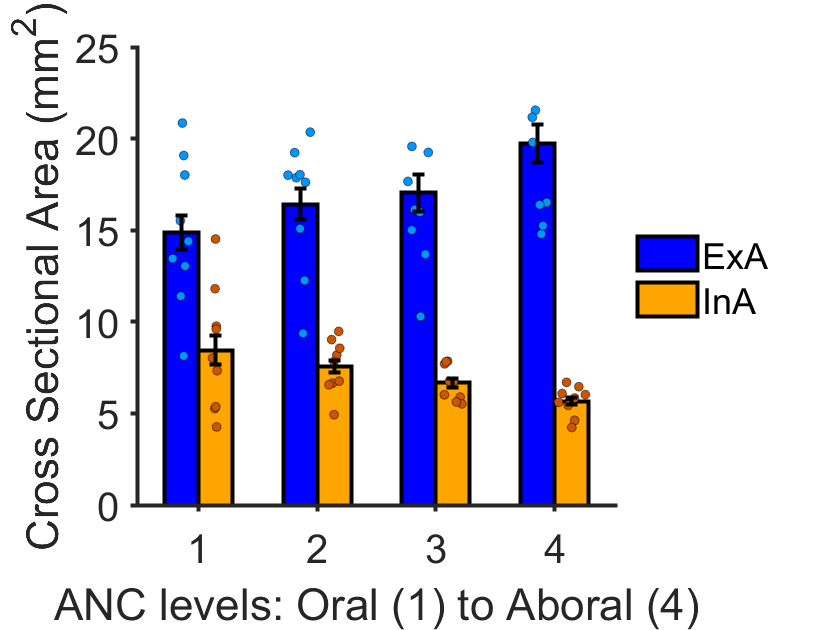

clear x 

% plot 
figure, 
b = bar(splitArea, 'BarWidth', 1, 'LineWidth', 2);
b(1, 1).FaceColor = blue;
b(1, 2).FaceColor = orange;
hold on 
[ngroups,nbars] = size(splitArea);

% Get the x coordinate of the bars
for i = 1:nbars
    x(i, :) = b(i).XEndPoints;
end
x = x';

% add swarm chart
areaIn = area((widthX(:,4)==1),1)./1000;
areaEx = area((widthX(:,4)==2),1)./1000;
numCon = size(areaIn,1)/size(x,1);
makeAxis1 = repmat(x(:,2),[1, numCon]);
xValues1 = reshape(makeAxis1.',1,[]);
makeAxis3 = repmat(x(:,1),[1, numCon]);
xValues3 = reshape(makeAxis3.',1,[]);

swarmchart(xValues1', (areaIn), 20,orange2,'Filled','MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5,'XJitter', 'density', 'XJitterWidth',0.25);
swarmchart(xValues3', (areaEx), 20,blue2,'Filled','MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5,'XJitter', 'density', 'XJitterWidth',0.25);

% add error bar
er = errorbar(x, (splitArea), (splitSEM), LineStyle="none", color= 'k', LineWidth = 2);

% Set plot parameters 
ylim([0,25])
ylabel('Cross Sectional Area (mm^2)')
xlabel('ANC levels: Oral (1) to Aboral (4)')
l = legend('ExA', 'InA');
l.EdgeColor = 'None';
l.Location = 'eastoutside';
axis normal
ax = gca; 
ax.FontSize = 20;
ax.FontName = 'Helvetica';
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 2;